# Examine Dual-List Session using Temporal Field Bayes - Lag Effect

fileDirs = [{'D:\WorkBigDataFiles\PFC\Dual List Sessions\GE11_Session146'},...
    {'D:\WorkBigDataFiles\PFC\Dual List Sessions\GE13_Session103'},...
    {'D:\WorkBigDataFiles\PFC\Dual List Sessions\GE17_Session110'}];
% fileDirs = [{'D:\WorkBigDataFiles\PFC\Dual List Sessions\GE13_Session103'},...
%     {'D:\WorkBigDataFiles\PFC\Dual List Sessions\GE17_Session110'}];

numChancePerms = 10;

postCLim = [0 0.05];

cMap = load('roma.mat'); % flip
cMap = cMap.(cell2mat(fieldnames(cMap)));
cMap = flipud(cMap);
cMapNanW = cMap;
cMapNanW(1,:) = ones(1,3);

## Compile DL TIP data

tic;
for ani = 1:length(fileDirs)
    %% Create & setup initial object and data variables (if initial file)
    mlb = MLB_SM(fileDirs{ani});
    % Create Analysis Variables
    if ani == 1 
        % Hold Durations
        trialHoldDurs = cell(length(mlb.odrVect), 1, length(fileDirs));
        % Real Posteriors
        lag_Interval = repmat({cell(size(mlb.lagVect))},[2,2]);
        lag_Trial = repmat({cell(size(mlb.lagVect))},[2,2]);
        % Chance Posteriors
        chancePDF = cell(length(mlb.odrVect), 1);
        chanceOdr = cell(length(mlb.odrVect), 1);
    end
    mlb.binSize = 200;
    mlb.dsRate = 50;
    mlb.windows = {[-800 2000]};
    mlb.bayesType = 1;

    %% Process Port Entry Aligned Observations
    mlb.alignments = {'PokeIn'};
    mlb.SetLikes_ISC;
    mlb.Process_LikelyL1O;
    tempOdrDecodes = cellfun(@(a){mlb.TabulateBayesPost(a,mlb.decodeIDvects(:,4))}, mlb.post);

    %% Extract Hold Durations
    iscTrlNdxs = find(~isnan(mlb.likeTrlIDs));
    holdDurs = arrayfun(@(a)mlb.trialInfo(mlb.likeTrlIDs(a)).PokeOutIndex - mlb.trialInfo(mlb.likeTrlIDs(a)).PokeInIndex, iscTrlNdxs);
    hdTrlMtx = nan(size(mlb.likeTrlIDs));
    hdTrlMtx(iscTrlNdxs) = holdDurs;

    %% Extract Interval and Trial Means Per Trial
    for obsvT = 1:length(mlb.odrVect)
%         if mod(mlb.odrVect(obsvT),10)==1
%             continue;
%         else
            curOdor = tempOdrDecodes{obsvT};
            temp_IntervalMean = mean(curOdor(mlb.obsvTimeVect<0,:,:),1);
            temp_TrialMean = nan(size(temp_IntervalMean));
            for trl = 1:size(curOdor,3)
                temp_TrialMean(:,:,trl) = mean(curOdor(mlb.obsvTimeVect>=0 & (mlb.obsvTimeVect <= (hdTrlMtx(obsvT,1,trl))/mlb.sampleRate),:,trl),1);
            end
%             temp_IntervalMean(:,mod(mlb.odrVect,10)==1,:) = nan;
%             temp_TrialMean(:,mod(mlb.odrVect,10)==1,:) = nan;

            [seqID,~] = find(mlb.odrSeqs==mlb.odrVect(obsvT));
            sameSeqLog = (1:size(mlb.odrSeqs,1))==seqID;
            sameSeq = mlb.odrSeqs(sameSeqLog,:);
            othrSeq = mlb.odrSeqs(~sameSeqLog,:);
            for p = 1:mlb.seqLength
                curLag = p-mod(mlb.odrVect(obsvT),10);
                curLagVectNdx = mlb.lagVect==curLag;
                sameSeq_OdorPos = mlb.odrVect==sameSeq(p);
                othrSeq_OdorPos = mlb.odrVect==othrSeq(p);
                lag_Interval{sameSeqLog,sameSeqLog}{curLagVectNdx} = [lag_Interval{sameSeqLog,sameSeqLog}{curLagVectNdx}; squeeze(temp_IntervalMean(:,sameSeq_OdorPos,~isnan(temp_IntervalMean(:,sameSeq_OdorPos,:))))];
                lag_Interval{sameSeqLog,~sameSeqLog}{curLagVectNdx} = [lag_Interval{sameSeqLog,~sameSeqLog}{curLagVectNdx}; squeeze(temp_IntervalMean(:,othrSeq_OdorPos,~isnan(temp_IntervalMean(:,othrSeq_OdorPos,:))))];
                lag_Trial{sameSeqLog,sameSeqLog}{curLagVectNdx} = [lag_Trial{sameSeqLog,sameSeqLog}{curLagVectNdx}; squeeze(temp_TrialMean(:,sameSeq_OdorPos,~isnan(temp_TrialMean(:,sameSeq_OdorPos,:))))];
                lag_Trial{sameSeqLog,~sameSeqLog}{curLagVectNdx} = [lag_Trial{sameSeqLog,~sameSeqLog}{curLagVectNdx}; squeeze(temp_TrialMean(:,othrSeq_OdorPos,~isnan(temp_TrialMean(:,othrSeq_OdorPos,:))))];
            end
%         end
    end
end

Compiling StatMatrix Data....Completed
Compiling StatMatrix Data....Completed
Compiling StatMatrix Data....Completed


toc

Elapsed time is 37.602232 seconds.


## Plot Lags Pretty Like

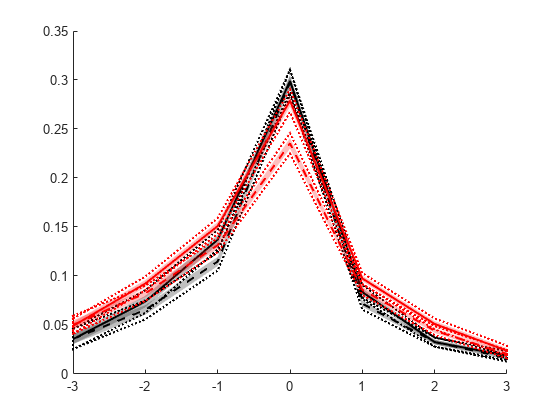

temp_temp_interval_Match = lag_Interval(logical(eye(2)));
temp_temp_interval_Match = reshape([temp_temp_interval_Match{:}], [length(mlb.lagVect),2])';
temp_temp_interval_NonMatch = lag_Interval(~logical(eye(2)));
temp_temp_interval_NonMatch = reshape([temp_temp_interval_NonMatch{:}], [length(mlb.lagVect),2])';
temp_interval_Match = cell(size(mlb.lagVect));
temp_interval_NonMatch = cell(size(mlb.lagVect));
temp_temp_trial_Match = lag_Trial(logical(eye(2)));
temp_temp_trial_Match = reshape([temp_temp_trial_Match{:}], [length(mlb.lagVect),2])';
temp_temp_trial_NonMatch = lag_Trial(~logical(eye(2)));
temp_temp_trial_NonMatch = reshape([temp_temp_trial_NonMatch{:}], [length(mlb.lagVect),2])';
temp_trial_Match = cell(size(mlb.lagVect));
temp_trial_NonMatch = cell(size(mlb.lagVect));
for lag = 1:length(mlb.lagVect)
    temp_interval_Match{lag} = cell2mat(temp_temp_interval_Match(:,lag));
    temp_interval_NonMatch{lag} = cell2mat(temp_temp_interval_NonMatch(:,lag));
    temp_trial_Match{lag} = cell2mat(temp_temp_trial_Match(:,lag));
    temp_trial_NonMatch{lag} = cell2mat(temp_temp_trial_NonMatch(:,lag));
end
maxNumVals = max(cellfun(@(a)length(a),temp_interval_Match));
interval_Match = nan(maxNumVals,length(mlb.lagVect));
interval_NonMatch = nan(maxNumVals,length(mlb.lagVect));
trial_Match = nan(maxNumVals,length(mlb.lagVect));
trial_NonMatch = nan(maxNumVals,length(mlb.lagVect));
for lag = 1:length(mlb.lagVect)
    interval_Match(1:length(temp_interval_Match{lag}),lag) = temp_interval_Match{lag};
    interval_NonMatch(1:length(temp_interval_NonMatch{lag}),lag) = temp_interval_NonMatch{lag};
    trial_Match(1:length(temp_trial_Match{lag}),lag) = temp_trial_Match{lag};
    trial_NonMatch(1:length(temp_trial_NonMatch{lag}),lag) = temp_trial_NonMatch{lag};
end

figure
iMatch = mlb.PlotMeanVarLine(mlb.lagVect, interval_Match,1,0.05,'k');
iNmatch = mlb.PlotMeanVarLine(mlb.lagVect, interval_NonMatch, 1, 0.05, 'k');
set(iNmatch, 'linestyle', '--');
tMatch = mlb.PlotMeanVarLine(mlb.lagVect, trial_Match, 1, 0.05, 'r'); 
tNmatch = mlb.PlotMeanVarLine(mlb.lagVect, trial_NonMatch, 1, 0.05, 'r'); 
set(tNmatch, 'linestyle', '--');

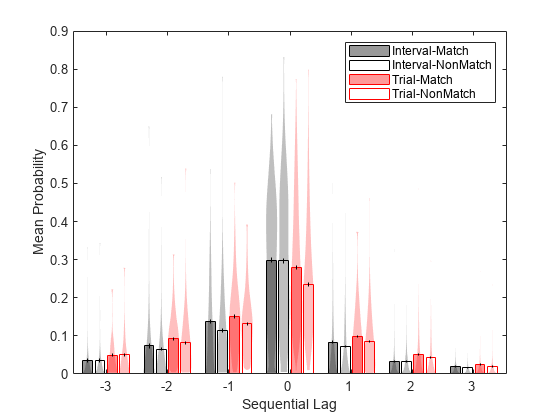


figure;
for lag = 1:length(mlb.lagVect)
    p(1) = mlb.PlotMeanVarViolin(lag*5-2, interval_Match(:,lag), 1, 0.05, 'k', 'filled');
    hold on;
    p(2) = mlb.PlotMeanVarViolin(lag*5-1, interval_NonMatch(:,lag), 1, 0.05,'k');
    p(3) = mlb.PlotMeanVarViolin(lag*5, trial_Match(:,lag), 1, 0.05, 'r', 'filled');
    p(4) = mlb.PlotMeanVarViolin(lag*5+1, trial_NonMatch(:,lag), 1, 0.05, 'r');
end
set(gca,'xtick', (1:length(mlb.lagVect))*5-0.5, 'xticklabels', mlb.lagVect)
legend(p, [{'Interval-Match'}, {'Interval-NonMatch'}, {'Trial-Match'},{'Trial-NonMatch'}]);
xlabel('Sequential Lag');
ylabel('Mean Probability');

[h,p,ci,stats] = ttest2(trial_Match(:,mlb.lagVect==0), trial_NonMatch(:,mlb.lagVect==0))

h = 1

p = 5.4785e-08

ci =     0.0279
    0.0592


stats = struct with fields:
    tstat: 5.4646
       df: 1408
       sd: 0.1497


## Run ANOVAs

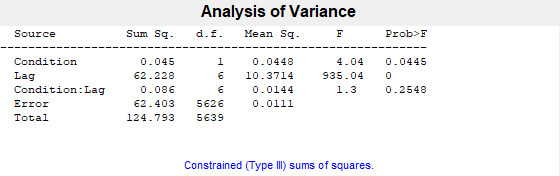

intP =     0.0445
         0
    0.2548


intTBL = 6×7 cell array
    {'Source'       }    {'Sum Sq.' }    {'d.f.'}    {'Singular?'}    {'Mean Sq.'}    {'F'       }    {'Prob>F'  }
    {'Condition'    }    {[  0.0448]}    {[   1]}    {[        0]}    {[  0.0448]}    {[  4.0392]}    {[  0.0445]}
    {'Lag'          }    {[ 62.2284]}    {[   6]}    {[        0]}    {[ 10.3714]}    {[935.0399]}    {[       0]}
    {'Condition:Lag'}    {[  0.0863]}    {[   6]}    {[        0]}    {[  0.0144]}    {[  1.2969]}    {[  0.2548]}
    {'Error'        }    {[ 62.4032]}    {[5626]}    {[        0]}    {[  0.0111]}    {0×0 double}    {0×0 double}
    {'Total'        }    {[124.7926]}    {[5639]}    {[        0]}    {0×0 double}    {0×0 double}    {0×0 double}


intSTATS = struct with fields:
         source: 'anovan'
          resid: [5640×1 double]
         coeffs: [24×1 double]
            Rtr: [14×14 double]
       rowbasis: [14×24 double]
            dfe: 5626
            mse: 0.0111
    nullproject: [24×14 double]
          terms: [3×2 double]
        nlevels: [2×1 double]
     continuous: [0 0]
         vmeans: [2×1 double]
       termcols: [4×1 double]
     coeffnames: {24×1 cell}
           vars: [24×2 double]
       varnames: {2×1 cell}
       grpnames: {2×1 cell}
        vnested: []
            ems: [4×4 double]
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


condIDs = repmat({cell(size(mlb.lagVect))},[1,4]);
lagIDs = repmat({cell(size(mlb.lagVect))},[1,4]);
matchIDs = repmat({cell(size(mlb.lagVect))},[1,4]);
trainIDs = repmat({cell(size(mlb.lagVect))},[1,4]);
testIDs = repmat({cell(size(mlb.lagVect))},[1,4]);
trlLbls = repmat({cell(size(mlb.lagVect))},[1,4]);
intLbls = repmat({cell(size(mlb.lagVect))},[1,4]);
for cond = 1:numel(lag_Interval)
    [r,c] = ind2sub(size(lag_Interval),cond);
%     condLbl = {sprintf('%i_%i',r,c)};
    if r==c
        matchLbl = true;
    else
        matchLbl = false;
    end
    for lagV = 1:length(mlb.lagVect)
        lagLbl = mlb.lagVect(lagV);
        condIDs{cond}{lagV} = repmat(cond,fliplr(size(lag_Interval{cond}{lagV})));
        lagIDs{cond}{lagV} = repmat(lagLbl,fliplr(size(lag_Interval{cond}{lagV})));
        trainIDs{cond}{lagV} = repmat(r,fliplr(size(lag_Interval{cond}{lagV})));
        testIDs{cond}{lagV} = repmat(c,fliplr(size(lag_Interval{cond}{lagV})));
        matchIDs{cond}{lagV} = repmat(matchLbl,fliplr(size(lag_Interval{cond}{lagV})));
        trlLbls{cond}{lagV} = true(fliplr(size(lag_Interval{cond}{lagV})));
        intLbls{cond}{lagV} = false(fliplr(size(lag_Interval{cond}{lagV})));
    end
end

intANOVAdta = cellfun(@(a){cell2mat(a(:))},lag_Interval);
trlANOVAdta = cellfun(@(a){cell2mat(a(:))},lag_Trial);
condIDsVects = cellfun(@(a){[a{:}]},condIDs);
lagIDsVects = cellfun(@(a){[a{:}]},lagIDs);
trainIDsVects = cellfun(@(a){[a{:}]},trainIDs);
testIDsVects= cellfun(@(a){[a{:}]},testIDs);
matchIDsVects = cellfun(@(a){[a{:}]},matchIDs);
trlLblsVects = cellfun(@(a){[a{:}]},trlLbls);
intLblsVects = cellfun(@(a){[a{:}]},intLbls);

[intP,intTBL,intSTATS] = anovan(cell2mat(intANOVAdta(:)), {[matchIDsVects{:}]', [lagIDsVects{:}]'}, 'model', 'interaction', 'varnames', {'Condition', 'Lag'})

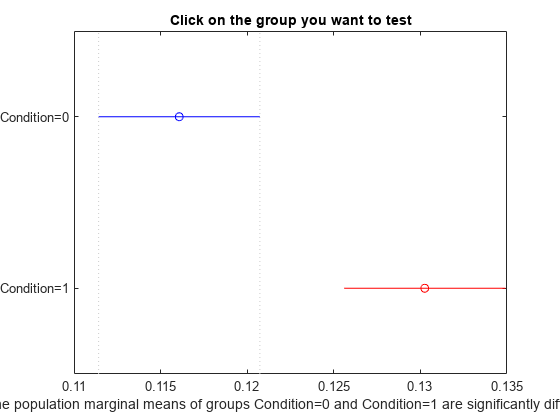

ans =     1.0000    2.0000   -0.0130   -0.0066   -0.0002    0.0445


multcompare(intSTATS,'Dimension',[1], 'CriticalValueType', 'bonferroni')

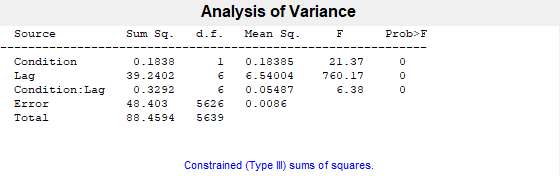

trlP = 1.0e-05 *

    0.3873
         0
    0.1051


trlTBL = 6×7 cell array
    {'Source'       }    {'Sum Sq.'}    {'d.f.'}    {'Singular?'}    {'Mean Sq.'}    {'F'       }    {'Prob>F'    }
    {'Condition'    }    {[ 0.1838]}    {[   1]}    {[        0]}    {[  0.1838]}    {[ 21.3691]}    {[3.8730e-06]}
    {'Lag'          }    {[39.2402]}    {[   6]}    {[        0]}    {[  6.5400]}    {[760.1656]}    {[         0]}
    {'Condition:Lag'}    {[ 0.3292]}    {[   6]}    {[        0]}    {[  0.0549]}    {[  6.3772]}    {[1.0514e-06]}
    {'Error'        }    {[48.4030]}    {[5626]}    {[        0]}    {[  0.0086]}    {0×0 double}    {0×0 double  }
    {'Total'        }    {[88.4594]}    {[5639]}    {[        0]}    {0×0 double}    {0×0 double}    {0×0 double  }


trlSTATS = struct with fields:
         source: 'anovan'
          resid: [5640×1 double]
         coeffs: [24×1 double]
            Rtr: [14×14 double]
       rowbasis: [14×24 double]
            dfe: 5626
            mse: 0.0086
    nullproject: [24×14 double]
          terms: [3×2 double]
        nlevels: [2×1 double]
     continuous: [0 0]
         vmeans: [2×1 double]
       termcols: [4×1 double]
     coeffnames: {24×1 cell}
           vars: [24×2 double]
       varnames: {2×1 cell}
       grpnames: {2×1 cell}
        vnested: []
            ems: [4×4 double]
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []



[trlP,trlTBL,trlSTATS] = anovan(cell2mat(trlANOVAdta(:)), {[matchIDsVects{:}], [lagIDsVects{:}]}, 'model', 'interaction', 'varnames', {'Condition', 'Lag'})

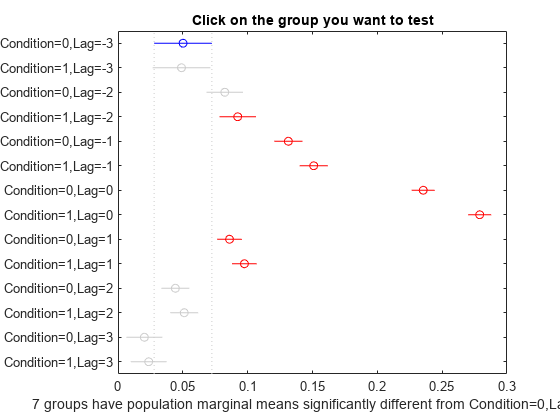

ans =     1.0000    2.0000   -0.0409    0.0012    0.0433    1.0000
    1.0000    3.0000   -0.0680   -0.0322    0.0036    0.1699
    1.0000    4.0000   -0.0780   -0.0422   -0.0064    0.0042
    1.0000    5.0000   -0.1147   -0.0812   -0.0477    0.0000
    1.0000    6.0000   -0.1343   -0.1008   -0.0673    0.0000
    1.0000    7.0000   -0.2174   -0.1852   -0.1531    0.0000
    1.0000    8.0000   -0.2609   -0.2288   -0.1967    0.0000
    1.0000    9.0000   -0.0684   -0.0358   -0.0033    0.0131
    1.0000   10.0000   -0.0799   -0.0473   -0.0147    0.0000
    1.0000   11.0000   -0.0275    0.0059    0.0393    1.0000


figure; multcompare(trlSTATS,'Dimension',[1,2], 'CriticalValueType', 'bonferroni')

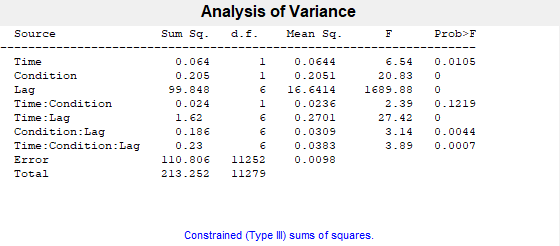

fullP =     0.0105
    0.0000
         0
    0.1219
    0.0000
    0.0044
    0.0007


fullTBL = 10×7 cell array
    {'Source'            }    {'Sum Sq.' }    {'d.f.' }    {'Singular?'}    {'Mean Sq.'}    {'F'         }    {'Prob>F'    }
    {'Time'              }    {[  0.0644]}    {[    1]}    {[        0]}    {[  0.0644]}    {[    6.5427]}    {[    0.0105]}
    {'Condition'         }    {[  0.2051]}    {[    1]}    {[        0]}    {[  0.2051]}    {[   20.8253]}    {[5.0845e-06]}
    {'Lag'               }    {[ 99.8482]}    {[    6]}    {[        0]}    {[ 16.6414]}    {[1.6899e+03]}    {[         0]}
    {'Time:Condition'    }    {[  0.0236]}    {[    1]}    {[        0]}    {[  0.0236]}    {[    2.3933]}    {[    0.1219]}
    {'Time:Lag'          }    {[  1.6204]}    {[    6]}    {[        0]}    {[  0.2701]}    {[   27.4243]}    {[1.1368e-32]}
    {'Condition:Lag'     }    {[  0.1857]}    {[    6]}    {[        0]}    {[  0.0309]}    {[    3.1427]}    {[    0.0044]}
    {'Time:Condition:Lag'}    {[  0.2298]}    {[    6]}    {[        0]}    {[  0.0383]}    {[    3

fullSTATS = struct with fields:
         source: 'anovan'
          resid: [11280×1 double]
         coeffs: [72×1 double]
            Rtr: [28×28 double]
       rowbasis: [28×72 double]
            dfe: 11252
            mse: 0.0098
    nullproject: [72×28 double]
          terms: [7×3 double]
        nlevels: [3×1 double]
     continuous: [0 0 0]
         vmeans: [3×1 double]
       termcols: [8×1 double]
     coeffnames: {72×1 cell}
           vars: [72×3 double]
       varnames: {3×1 cell}
       grpnames: {3×1 cell}
        vnested: []
            ems: [8×8 double]
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []



[fullP,fullTBL,fullSTATS] = anovan([cell2mat(intANOVAdta(:));cell2mat(trlANOVAdta(:))], {[[intLblsVects{:}],[trlLblsVects{:}]], repmat([matchIDsVects{:}],[1,2]), repmat([lagIDsVects{:}],[1,2])}, 'model', 'full', 'varnames', {'Time','Condition', 'Lag'})

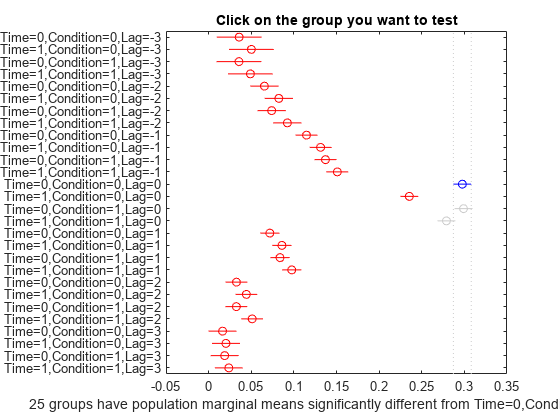

ans =     1.0000    2.0000   -0.0641   -0.0143    0.0355    1.0000
    1.0000    3.0000   -0.0495    0.0003    0.0501    1.0000
    1.0000    4.0000   -0.0630   -0.0132    0.0367    1.0000
    1.0000    5.0000   -0.0719   -0.0296    0.0127    1.0000
    1.0000    6.0000   -0.0889   -0.0465   -0.0042    0.0101
    1.0000    7.0000   -0.0804   -0.0381    0.0042    0.2195
    1.0000    8.0000   -0.0989   -0.0565   -0.0142    0.0001
    1.0000    9.0000   -0.1186   -0.0789   -0.0393    0.0000
    1.0000   10.0000   -0.1352   -0.0955   -0.0559    0.0000
    1.0000   11.0000   -0.1409   -0.1012   -0.0616    0.0000


figure; multcompare(fullSTATS,'Dimension',[1,2,3], 'CriticalValueType', 'bonferroni')